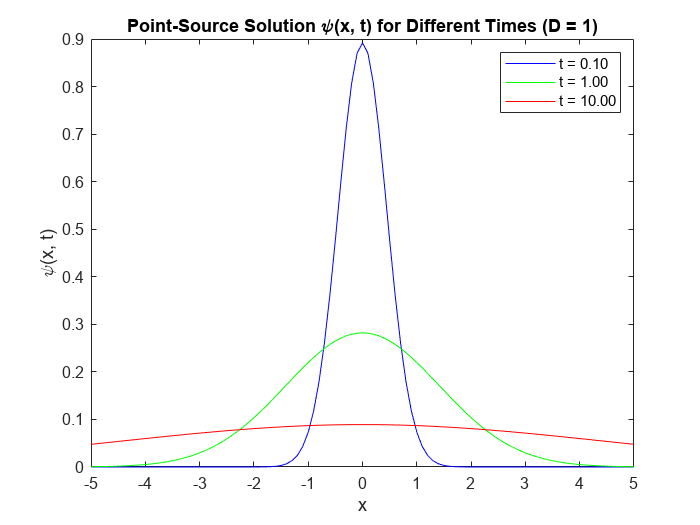

% Define parameters
D = 1;  % Diffusion coefficient
t1 = 0.1;  % Small time value
t2 = 1;    % Moderate time value
t3 = 10;   % Large time value
x_range = -5:0.1:5;  % Moderate x range (symmetric)
dt=0.01;
t_range = t1:dt:t3; 
% Calculate ψ(x, t) for each time value
psi1 = (4*pi*D*t1)^(-0.5) * exp(-x_range.^2 ./ (4*D*t1));
psi2 = (4*pi*D*t2)^(-0.5) * exp(-x_range.^2 ./ (4*D*t2));
psi3 = (4*pi*D*t3)^(-0.5) * exp(-x_range.^2 ./ (4*D*t3));

% Plot
figure;
plot(x_range, psi1, 'b-', 'DisplayName', sprintf('t = %.2f', t1)); hold on;
plot(x_range, psi2, 'g-', 'DisplayName', sprintf('t = %.2f', t2));
plot(x_range, psi3, 'r-', 'DisplayName', sprintf('t = %.2f', t3));
xlabel('x');
ylabel('\psi(x, t)');
title('Point-Source Solution \psi(x, t) for Different Times (D = 1)');
legend();

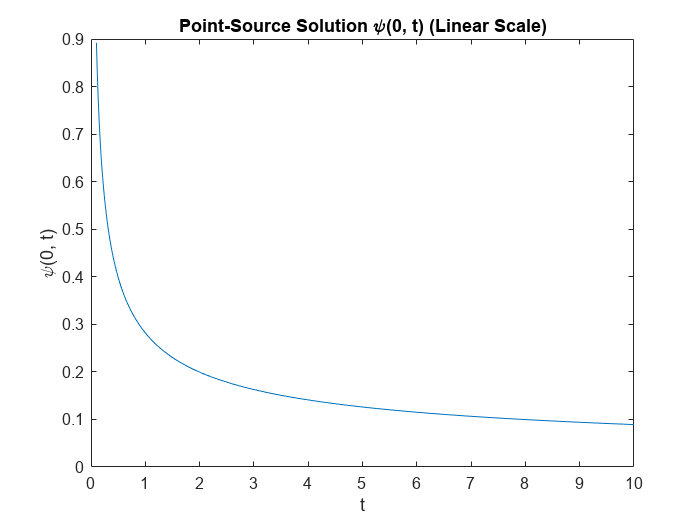



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate ψ(0, t) for all time values
psi_0_t = (4*pi*D*t_range).^(-0.5) * exp(0);  % Constant at x = 0

% Plot in linear scale
figure;
plot(t_range, psi_0_t);
xlabel('t');
ylabel('\psi(0, t)');
title('Point-Source Solution \psi(0, t) (Linear Scale)');

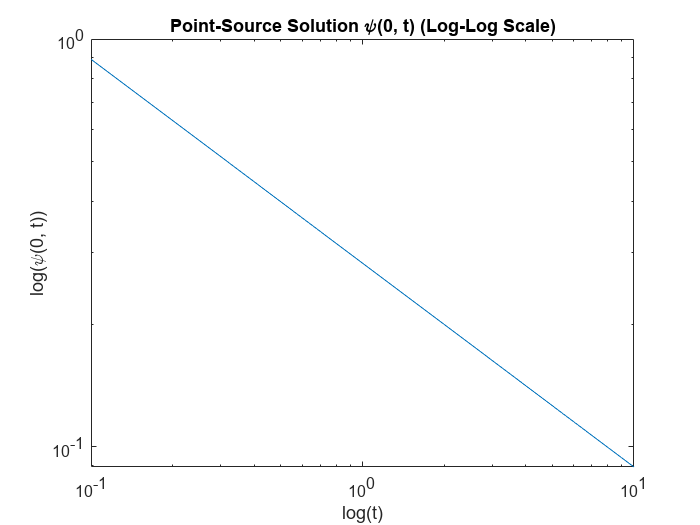


% Plot in log-log scale
figure;
loglog(t_range, psi_0_t);
xlabel('log(t)');
ylabel('log(\psi(0, t))');
title('Point-Source Solution \psi(0, t) (Log-Log Scale)');


% Calculate slope (approximately)
t_mid = t_range(floor(length(t_range)/2));
psi_mid = psi_0_t(floor(length(t_range)/2));
t_later = t_range(end);
psi_later = psi_0_t(end);
slope = (log(psi_later) - log(psi_mid)) / (log(t_later) - log(t_mid));
fprintf('Approximate slope in log-log plot: %.2f\n', slope);

Approximate slope in log-log plot: -0.50


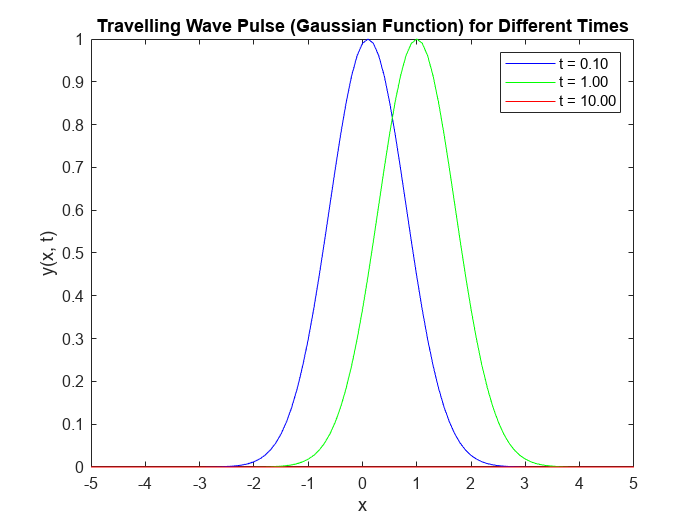

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Define parameters
y0 = 1; a = 1; v = 1;

% Plot y(x, t) for each time value
y1 = y0 * exp(-a * (x_range - v*t1).^2);
y2 = y0 * exp(-a * (x_range - v*t2).^2);
y3 = y0 * exp(-a * (x_range - v*t3).^2);

% Plot
figure;
plot(x_range, y1, 'b-', 'DisplayName', sprintf('t = %.2f', t1)); hold on;
plot(x_range, y2, 'g-', 'DisplayName', sprintf('t = %.2f', t2));
plot(x_range, y3, 'r-', 'DisplayName', sprintf('t = %.2f', t3));
xlabel('x');
ylabel('y(x, t)');
title('Travelling Wave Pulse (Gaussian Function) for Different Times');
legend();

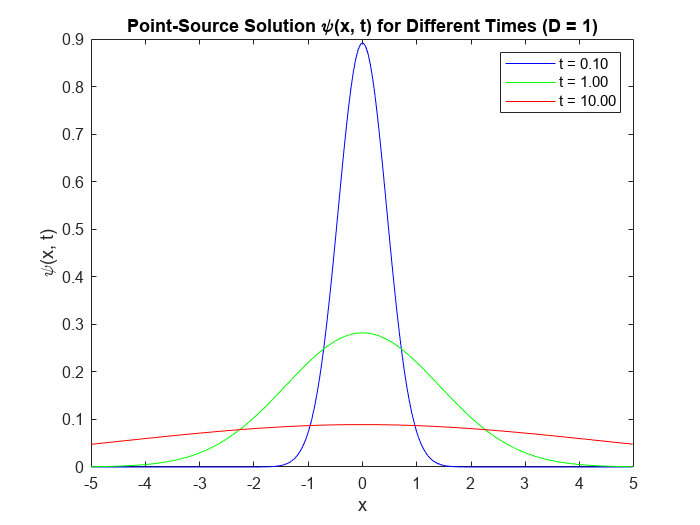

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Define parameters
D = 1;  % Diffusion coefficient
% Diffusion coefficient
t1 = 0.1;  % Small time value
t2 = 1;    % Moderate time value
t3 = 10;
dt = 0.001;  % Time step
dx = sqrt(2*D*dt);  % Spatial step (satisfies stability criterion)
x_range = -5:dx:5;  % Same x range as before
Nx = length(x_range);

% Initial condition
psi = zeros(1, Nx);
psi(Nx/2) = 1000;  % Initial concentration at x = 0
psi1 = (4*pi*D*t1)^(-0.5) * exp(-x_range.^2 ./ (4*D*t1));
psi2 = (4*pi*D*t2)^(-0.5) * exp(-x_range.^2 ./ (4*D*t2));
psi3 = (4*pi*D*t3)^(-0.5) * exp(-x_range.^2 ./ (4*D*t3));

for n = 1:1000  % Number of time steps (adjust for desired simulation time)
  dpsi_dt = D * (circshift(psi, 1) - 2*psi + circshift(psi, -1)) / (dx^2);
  psi = psi + dpsi_dt * dt;
end
% Calculate ψ(0, t) for all time values
psi_0_t = (4*pi*D*t_range).^(-0.5) * exp(0);  % Constant at x = 0


% Plot
figure;
plot(x_range, psi1, 'b-', 'DisplayName', sprintf('t = %.2f', t1)); hold on;
plot(x_range, psi2, 'g-', 'DisplayName', sprintf('t = %.2f', t2));
plot(x_range, psi3, 'r-', 'DisplayName', sprintf('t = %.2f', t3));
xlabel('x');
ylabel('\psi(x, t)');
title('Point-Source Solution \psi(x, t) for Different Times (D = 1)');
legend();


figure;
plot(t_range, psi_0_t);
xlabel('t');
ylabel('\psi(0, t)');
title('Point-Source Solution \psi(0, t) (Linear Scale)');


% Plot in log-log scale
figure;
loglog(t_range, psi_0_t);
xlabel('log(t)');
ylabel('log(\psi(0, t))');
title('Point-Source Solution \psi(0, t) (Log-Log Scale)');